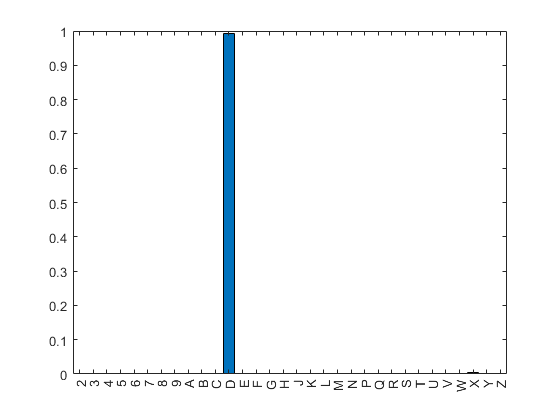

clear all;
path = "images/hard/226md.png";
load('CNN_net.mat', 'net');
[actual, prediction, scores] = makePredictions(path, net);

x = net.Layers(15).Classes;
x = x.';
% First Character
y = scores{5};
bar(x,y)

function [img1, img2, img3, img4, img5] = charSeparator_Ratio(img)
    im_off = img(:,30:size(img,2));
    mask = (im_off >=120).*255;
    x = sum(255-mask);
    b = x>=800;
    im_cut = im_off(:,b);
    p = round(size(im_cut,2)/5);
    img1 = imresize(im_cut(:,1:p),[28,28]);
    img2 = imresize(im_cut(:,p:2*p),[28,28]);
    img3 = imresize(im_cut(:,2*p:3*p),[28,28]);
    img4 = imresize(im_cut(:,3*p:4*p),[28,28]);
    img5 = imresize(im_cut(:,4*p:size(im_cut,2)),[28,28]);
end

function [result, scr] = getCharacters(path, net)
    
    img = rgb2gray(imread(path));
    characters = {};
    ans = '';
    [img1, img2, img3, img4, img5] = charSeparator_Ratio(img);
    scr = {};
    characters = [characters, img1];
    characters = [characters, img2];
    characters = [characters, img3];
    characters = [characters, img4];
    characters = [characters, img5];
    for k=1:size(characters, 2)
        folder = strcat('CNN_demo/',string(k));
        mkdir(folder);
        baseFileName = sprintf('%s.png', string(k));
        fullFileName = fullfile(folder, baseFileName);
        imwrite(characters{k}, fullFileName);
        imd = imageDatastore('CNN_demo/', ...
            'IncludeSubfolders',true);
        [YPred, scores] = classify(net,imd);
        arr = cellstr(classify(net,imd));
        ans = strcat(ans,arr);
        scr = [scr, scores];
        rmdir('CNN_demo','s');
    end
    result = ans{1};
end

function [actual, prediction, score] = makePredictions(path, net)
    [result, score] = getCharacters(path, net);
    str = strsplit(path, '/');
    str = strsplit(str{3}, '.');
    actual = str{1};
    prediction = result;
end